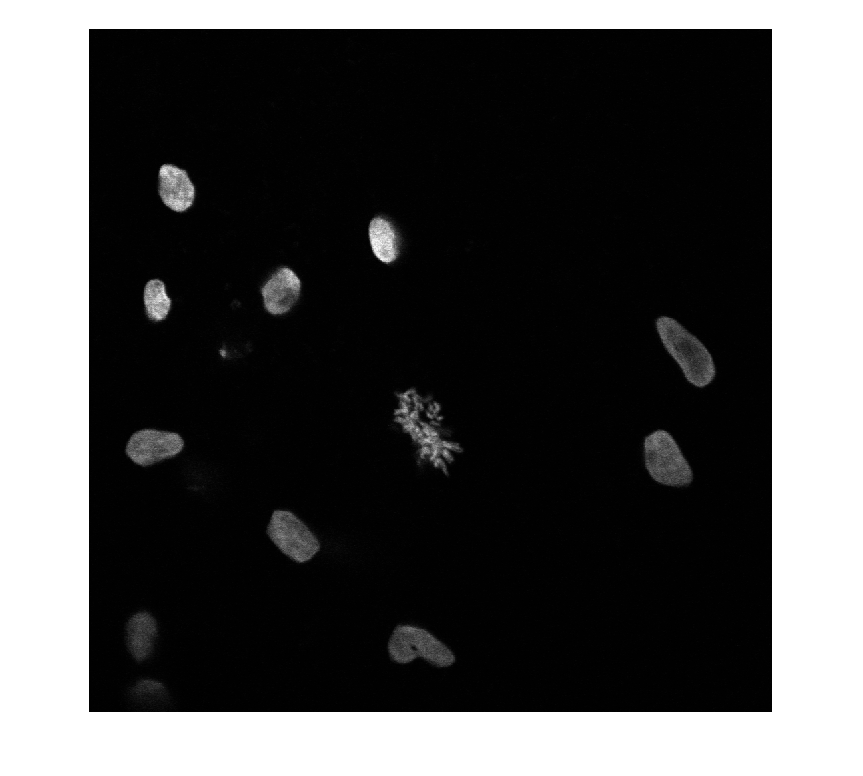

%% threshold
I_blue = imread("Chromosomes-blue.tif") ;
figure; imshow(I_blue);

% Method 1 with histogram equalization + median filter + manual threshold:

I_blue_eq = histeq(I_blue);
I_blue_eq_med = medfilt2(I_blue_eq, [30 30]);

% figure;
%subplot(1,2,1); imshow(I_blue_eq);
%subplot(1,2,2); imshow(I_blue_eq_med);

% imhist(I_blue_eq_med);

I_blue_threshold1 = I_blue_eq_med ;
I_blue_threshold1(I_blue_threshold1 > 6.2*10^4) = 2^16 ;
I_blue_threshold1(I_blue_threshold1 <= 6.2*10^4) = 0 ;


% Method 2 only manual threshold :

% imhist(I_blue);
I_blue_threshold2 = I_blue;
I_blue_threshold2(I_blue_threshold2 > 5000) = 2^16 ;
I_blue_threshold2(I_blue_threshold2 <= 5000) = 0 ;
 


% Method 3 Otsu :
[T,EM] = graythresh(I_blue_eq_med);
Iotsu = I_blue_eq_med; 
Iotsu(Iotsu>T*(2^16 -1)) = 2^16 -1;
Iotsu(Iotsu<=T*(2^16 -1)) = 0;
Iotsu_blue = logical(Iotsu);

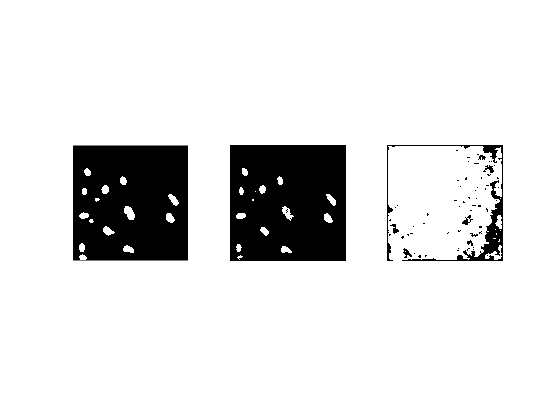

%%  Methods comparison :
figure ;
subplot(1,3,1); imshow(logical(I_blue_threshold1));
subplot(1,3,2); imshow(logical(I_blue_threshold2));
subplot(1,3,3); imshow(logical(Iotsu_blue));

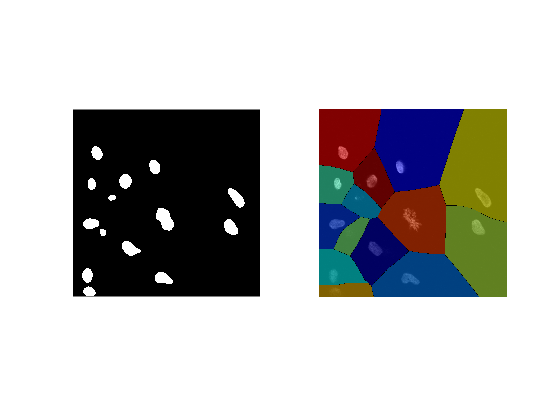

%%  Watershed : detect cells regions
map = bwdist(I_blue_threshold1);
L = watershed(map);
disp = labeloverlay(I_blue, L);
zones = max(unique(L)); % 13 distinct regions with threshold1

figure ;
subplot(1,2,1); imshow(logical(I_blue_threshold1));
subplot(1,2,2); imshow(disp);

%% Crop the cells from the image :

cells_blue = cell(zones, 1) ;
coord = zeros(2,2,zones) ;

for z=1:zones 
    display(z) 
    [r1, c1] = find(L==z);
    wsregion = zeros(max(r1)-min(r1)+1, max(c1)-min(c1)+1);
    for i=min(r1):max(r1)
        for j=min(c1):max(c1)
            if L(i,j) == z && I_blue_threshold1(i,j)==2^16-1
                wsregion(i-min(r1)+1,j-min(c1)+1) = 1;
            else 
                wsregion(i-min(r1)+1,j-min(c1)+1) = 0;
            end
        end
    end
    wsregion = logical(wsregion);
    [r2, c2] = find(wsregion==1);
    % attention au changement de base / d'indice avec la matrice wsregion (+min(r1)-1 ; +min(c1)-1) :
    coord(:, :, z) = [min(r2)+min(r1)-1 max(r2)+min(r1)-1 ; min(c2)+min(c1)-1 max(c2)+min(c1)-1];
    wsregion = wsregion(min(r2):max(r2), min(c2):max(c2)) ;
    cells_blue{z} = wsregion ;
    clear r1 r2 c1 c2 ;
end

z = uint8
1

z = uint8
2

z = uint8
3

z = uint8
4

z = uint8
5

z = uint8
6

z = uint8
7

z = uint8
8

z = uint8
9

z = uint8
10

z = uint8
11

z = uint8
12

z = uint8
13

z = uint8
14

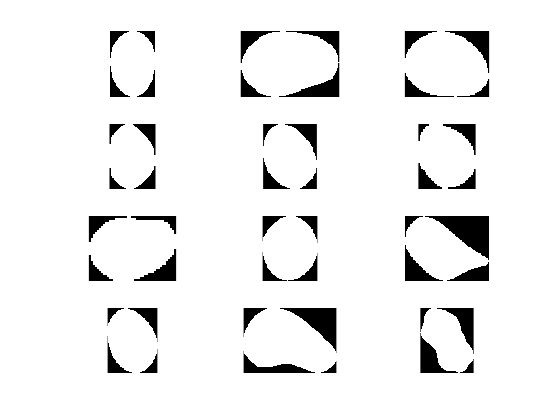

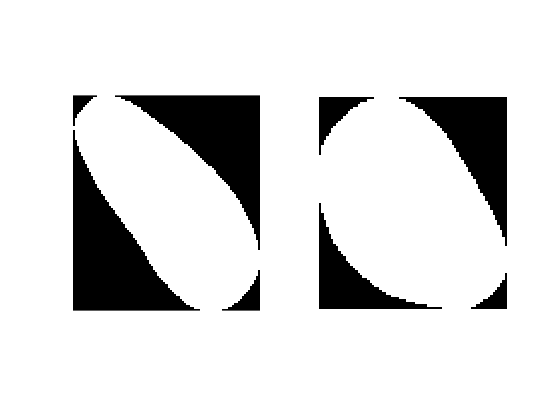


% Plot the cells from blue image
grid = double(4);
q = double(mod(zones, grid));
if q > 0
    figure;
    p = double(zones-q);
    for plotId=1:p
        subplot(grid, p/grid, plotId) ;
        imshow(cells_blue{plotId}) ;
    end
    figure;
    for plotId=1:q
        subplot(1, q, plotId) ;
        imshow(cells_blue{zones-plotId+1}) ;
    end
else
    figure;
    for plotId=1:zones
        subplot(grid, grid, plotId) ;
        imshow(cells_blue{plotId}) ;
    end
end

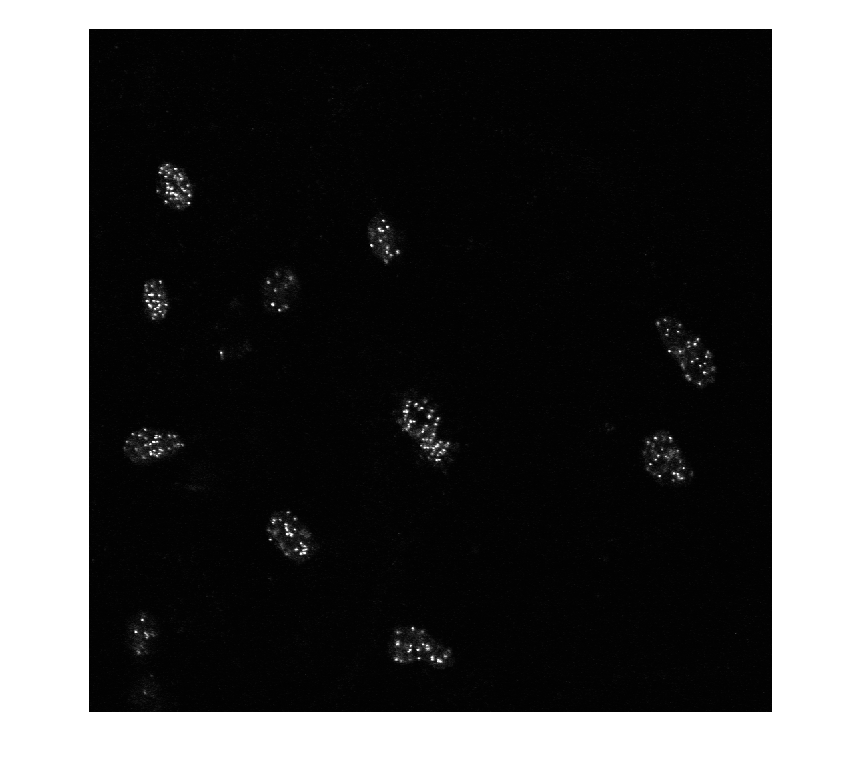


%% Crop the same region on the green image as in the blue image :

I_green = imread("Chromosomes-green.tif") ;
figure ; imshow(I_green) ;

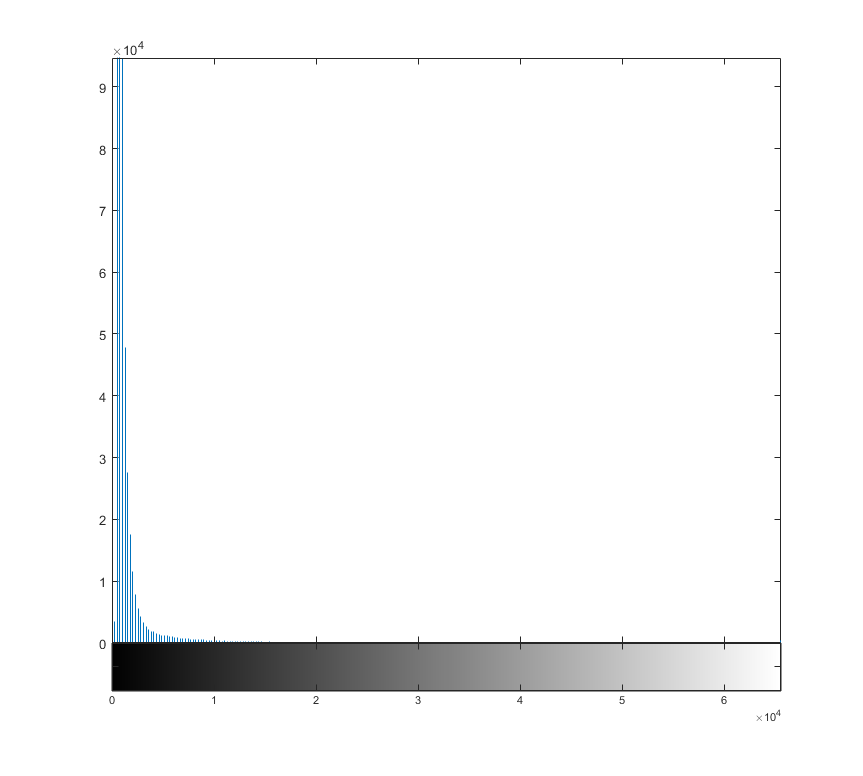

imhist(I_green)


cells_green = cell(zones, 1);
for z=1:size(coord,3)
    xmin = coord(1,1,z);
    xmax = coord(1,2,z);
    ymin = coord(2,1,z);
    ymax = coord(2,2,z);
    cells_green{z} = I_green(xmin:xmax, ymin:ymax);
    clear xmin xmax ymin ymax
end

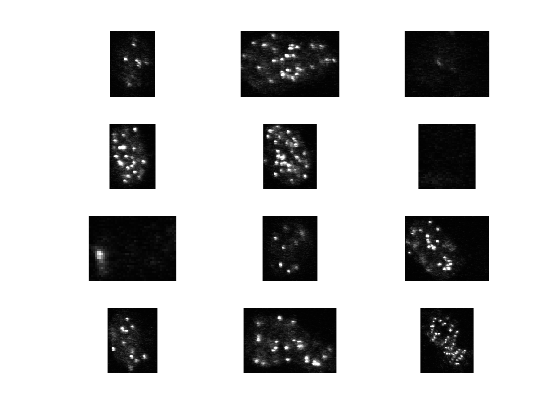

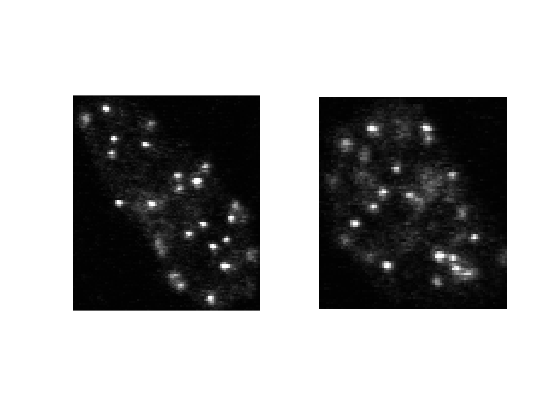


% Plot the cells from green image
grid = double(4);
q = double(mod(zones, grid));
if q > 0
    figure;
    p = double(zones-q);
    for plotId=1:p
        subplot(grid, p/grid, plotId) ;
        imshow(cells_green{plotId}) ;
    end
    figure;
    for plotId=1:q
        subplot(1, q, plotId) ;
        imshow(cells_green{zones-plotId+1}) ;
    end
else
    figure;
    for plotId=1:zones
        subplot(grid, grid, plotId) ;
        imshow(cells_green{plotId}) ;
    end
end



%% Isolate the maximums for each cells to detect the amount of chromosomes 
nb_chromosomes = zeros(1,zones);
fprintf("--------------\n HISTEQ \n--------------\n")

--------------
 HISTEQ 
--------------


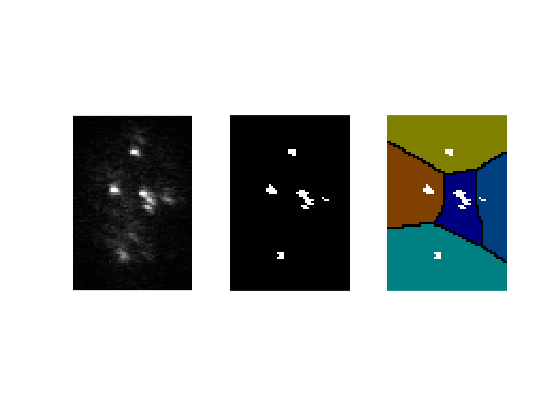

Cellule 1 : 5 chromosomes.


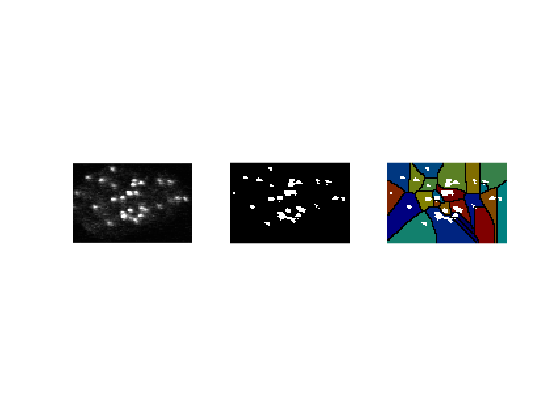

Cellule 2 : 24 chromosomes.


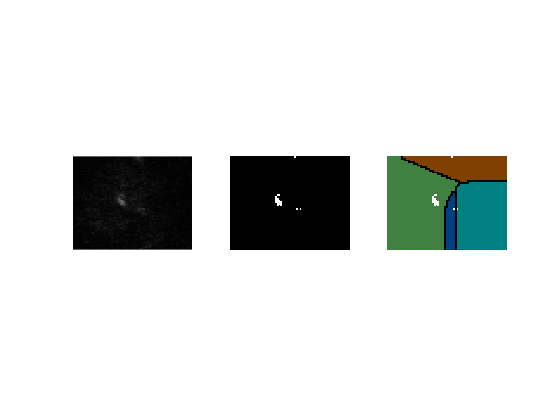

Cellule 3 : 4 chromosomes.


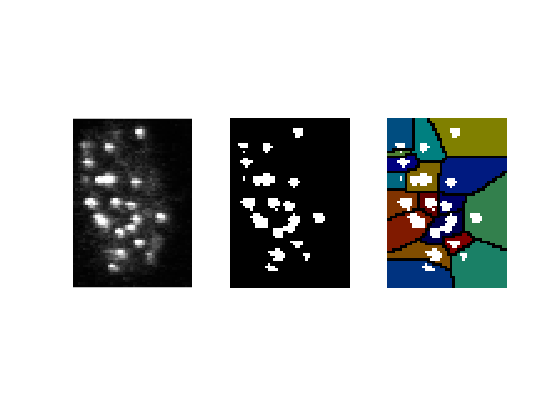

Cellule 

4 : 18 chromosomes.


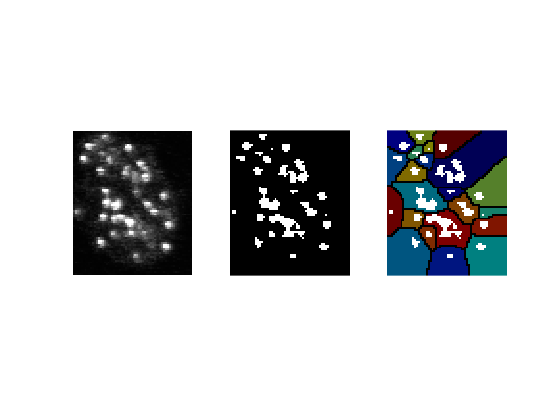

Cellule 5 : 22 chromosomes.


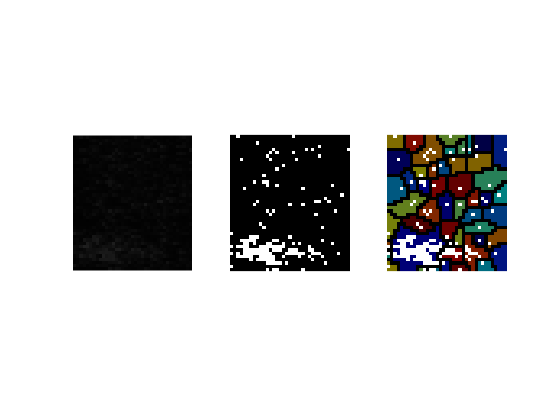

Cellule 6 : 50 chromosomes.


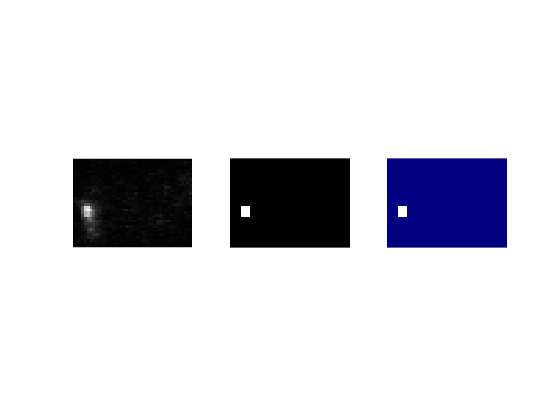

Cellule 7 : 1 chromosomes.


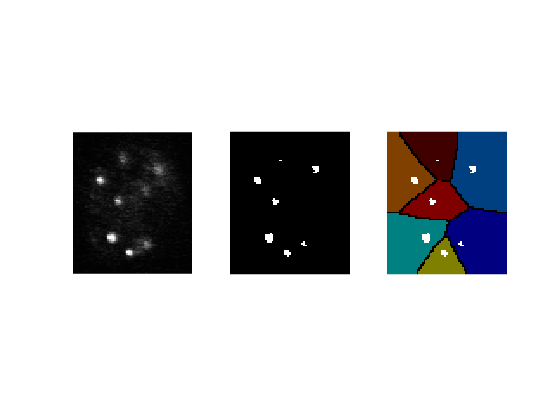

Cellule 8 : 7 chromosomes.


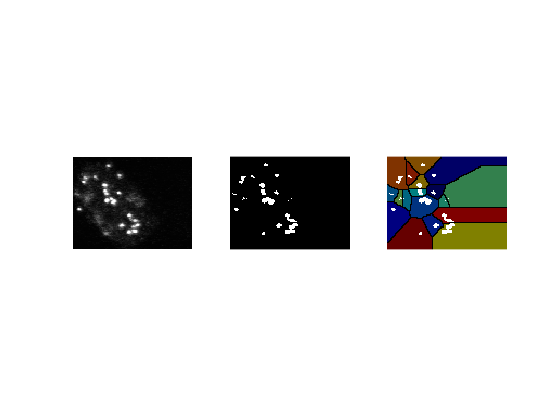

Cellule 9 : 18 chromosomes.


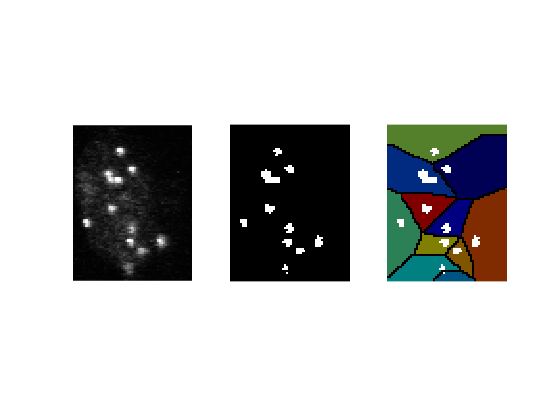

Cellule 10 : 11 chromosomes.


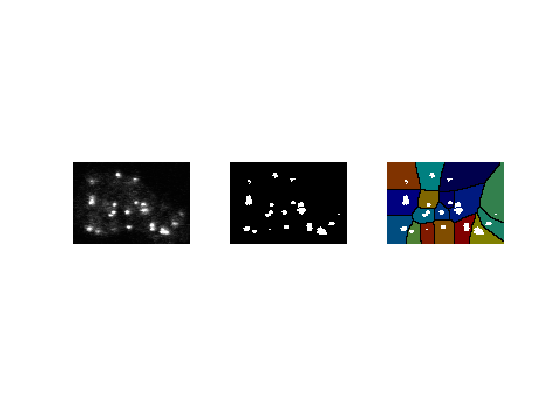

Cellule 11 : 17 chromosomes.


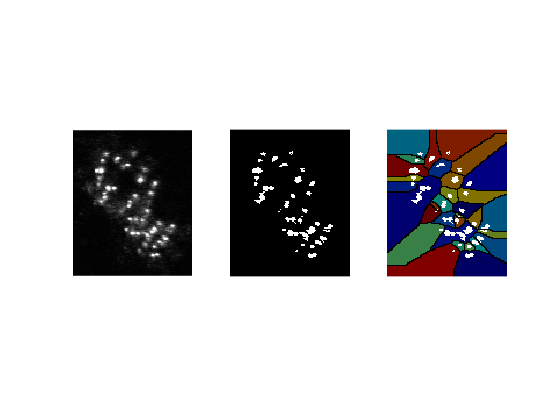

Cellule 12 : 32 chromosomes.


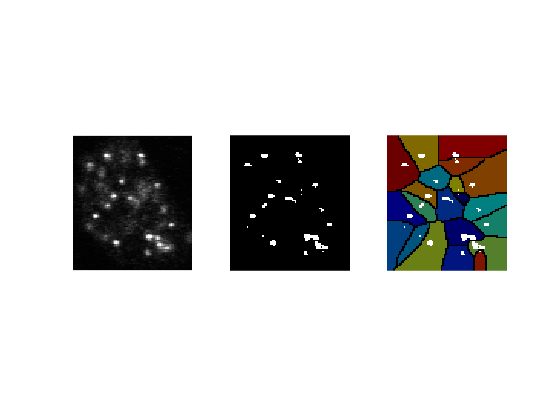

Cellule 13 : 21 chromosomes.


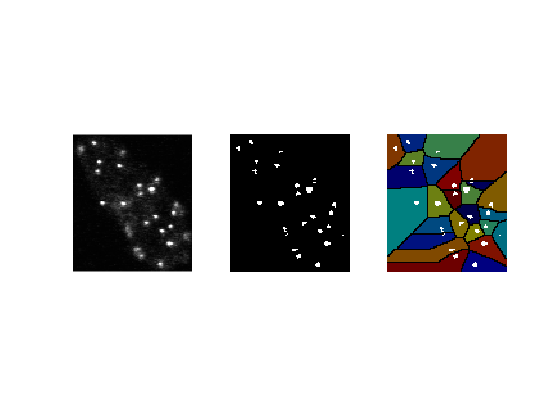

Cellule 14 : 26 chromosomes.


cells_green_thres = cell(zones, 1);

for z=1:double(zones)
    %seuil main : 
    maxval = max(max(cells_green{z}));
    im_tr = cells_green{z};
    im_tr(im_tr >= maxval*0.4) = 2^16-1 ;
    im_tr(im_tr < maxval*0.5) = 0 ;
    cells_green_thres{z} = im_tr ;

    %fait le water shed
    map_cell_by_cell_green = bwdist(im_tr);
    L = watershed(map_cell_by_cell_green);
    disp_cell= labeloverlay(single(im_tr), L);
    nb_chromosomes(z) = max(unique(L));
    
    % DECOMMMENTER POUR VOIR AFFICHAGE CELLULE PAR CELLULE : 
    % Affichage des cellules :
    figure;   
    subplot(1,3,1); imshow((cells_green{z}));
    subplot(1,3,2); imshow(logical(cells_green_thres{z}));
    subplot(1,3,3); imshow(disp_cell);
    
    clear im_tr L map_cell_by_cell_green disp
    fprintf("Cellule %d : %d chromosomes.\n", z, nb_chromosomes(z))
end


%%

%% Compute some stats